# 半参数模型

## 简介

**参数部分：**

以欧拉-牛顿动力学方程的矩阵形式为基础，在此基础上进行改进：

- 修改并优化了摩擦力模型；

- 添加了物理学约束；

- 使用了fmincon方法优化出参数；

**非参数部分：**

以LSTM网络为基础，对摩擦力的非线性部分进行拟合。

## 代码-参数部分：

### 加载数据与设置参数

addpath './semi-parameters'
warning off; clear; clc; 
config_LSTM;

### 计算回归矩阵

P = transform_parameters(opt_x);
friction_parameters = zeros(7, 5);
friction_parameters_tandard = zeros(7, 5);
for joint = Joint(1, 1) : Joint(end, 1)
    friction_parameters(joint, :) = [[opt_x(71 + (joint - 1) * 4 : 74 + (joint - 1) * 4)]', [opt_x(99 + (joint - 1))]];
end

load('data/filtering_data_no_downsampling.mat');
q_filt_0 = q_filt;
qd_filt_0 = qd_filt;
qdd_filt_0 = qdd_filt;
t_filt_0 = t_filt;

load('data/filted_No1_excitation_trajectory.mat');
q_filt_1 = q_filt;
qd_filt_1 = qd_filt;
qdd_filt_1 = qdd_filt;
t_filt_1 = t_filt;

load('data/filted_No2_excitation_trajectory.mat');
q_filt_2 = q_filt;
qd_filt_2 = qd_filt;
qdd_filt_2 = qdd_filt;
t_filt_2 = t_filt;

load('data/filted_No3_excitation_trajectory.mat');
q_filt_3 = q_filt;
qd_filt_3 = qd_filt;
qdd_filt_3 = qdd_filt;
t_filt_3 = t_filt;

load('data/filted_No4_excitation_trajectory.mat');
q_filt_4 = q_filt;
qd_filt_4 = qd_filt;
qdd_filt_4 = qdd_filt;
t_filt_4 = t_filt;

load('data/filted_No5_excitation_trajectory.mat');
q_filt_5 = q_filt;
qd_filt_5 = qd_filt;
qdd_filt_5 = qdd_filt;
t_filt_5 = t_filt;

q_filt = [q_filt_0; q_filt_1; q_filt_2; q_filt_3; q_filt_4; q_filt_5];
qd_filt = [qd_filt_0; qd_filt_1; qd_filt_2; qd_filt_3; qd_filt_4; qd_filt_5];
qdd_filt = [qdd_filt_0; qdd_filt_1; qdd_filt_2; qdd_filt_3; qdd_filt_4; qdd_filt_5];
t_filt = [t_filt_0; t_filt_1; t_filt_2; t_filt_3; t_filt_4; t_filt_5];

clearvars q q_filt_0 q_filt_1 q_filt_2 q_filt_3 q_filt_4 q_filt_5 ...
          qd qd_filt_0 qd_filt_1 qd_filt_2 qd_filt_3 qd_filt_4 qd_filt_5 ...
          qdd qdd_filt_0 qdd_filt_1 qdd_filt_2 qdd_filt_3 qdd_filt_4 qdd_filt_5 ...
          t_filt_0 t_filt_1 t_filt_2 t_filt_3 t_filt_4 t_filt_5;

g = 9.80665;
[n_sample, ~] = size(q_filt);
T = zeros(n_sample, 7);
T_idy = zeros(n_sample, 7);

for k = 1 : n_sample
    q = q_filt(k, :);
    qd = qd_filt(k, :);
    qdd = qdd_filt(k, :);
    T(k, :) = t_filt(k, :);
    ww = compute_regression_matrix(q, qd, qdd, 0);

    T_idy(k,:) = ww * P';

    for i = 1 : 7
        T_idy(k, i) = T_idy(k, i) + compute_Stribeck_friction(qd(1, i), friction_parameters(i, :), gamma);
    end
end

## 代码-非参数部分：

工作流程如下：

- 制作数据集；

- 划分数据集 & 转换格式；

- 搭建LSTM神经网络；

- 训练神经网络；

- 验证神经网络；

- 验证模型效果；

### 第一步：制作数据集

num_sample_point = size(q_filt, 1);
database = zeros(num_factors * size(Joint, 1), num_sample_point);
T_error = t_filt - T_idy;

for frame = 1 : num_sample_point
   database(:, frame) = [q_filt(frame, :)'; qd_filt(frame, :)'; qdd_filt(frame, :)'; T_error(frame, :)'];
end

### 第二步：划分数据集 & 转换格式

% 划分数据集
split = floor(num_sample_point * train_percent);
INPUT_TRAIN = database(1 : (num_factors - 1) * size(Joint, 1), 1 : split);
output_train = database((num_factors - 1) * size(Joint, 1) + 1 : end, 1 : split);
INPUT_TEST = database(1 : (num_factors - 1) * size(Joint, 1), split + 1 : end);
output_test = database((num_factors - 1) * size(Joint, 1) + 1 : end, split + 1 : end);

% 格式转换
input_train = cell(1, size(INPUT_TRAIN, 2));
input_test = cell(1, size(INPUT_TEST, 2));

for i = 1 : size(INPUT_TRAIN, 2)
    input_train{1, i} = INPUT_TRAIN(:, i);
end

for i = 1 : size(INPUT_TEST, 2)
    input_test{1, i} = INPUT_TEST(:, i);
end


### 第三步：定义LSTM神经网络

% 标准模型
layers = [
    sequenceInputLayer((num_factors - 1) * size(Joint, 1))        % 建立输入层

    lstmLayer(32, 'OutputMode', 'last')                           % LSTM层
    reluLayer                                                     % Relu激活层

    lstmLayer(16, 'OutputMode', 'last')                           % LSTM层
    reluLayer                                                     % Relu激活层

    lstmLayer(8, 'OutputMode', 'last')                            % LSTM层
    reluLayer                                                     % Relu激活层

    fullyConnectedLayer(7)                                        % 全连接层
    regressionLayer                                               % 回归层
];

% % 带自注意力层的模型
% layers = [
%     sequenceInputLayer((num_factors - 1) * size(Joint, 1))        % 建立输入层
% 
%     lstmLayer(32, 'OutputMode', 'last')                           % LSTM层
%     reluLayer                                                     % Relu激活层
% 
%     lstmLayer(16, 'OutputMode', 'last')                           % LSTM层
%     reluLayer                                                     % Relu激活层
% 
%     lstmLayer(8, 'OutputMode', 'last')                            % LSTM层
%     selfAttentionLayer(8, 64, "Name", "selfattention")            % 添加注意力层（自动生成上下文向量）
% 
%     fullyConnectedLayer(7)                                        % 全连接层
%     regressionLayer                                               % 回归层
%     ];

% % 实验模型
% layers = [
%     sequenceInputLayer((num_factors - 1) * size(Joint, 1))        % 建立输入层
% 
%     lstmLayer(32, 'OutputMode', 'last')                           % LSTM层
%     selfAttentionLayer(32, 64, "Name", "selfattention")
% 
%     fullyConnectedLayer(7)                                        % 全连接层
%     regressionLayer                                               % 回归层
%     ];

### LSTM参数设置

options = trainingOptions('adam', ...            % Adam 梯度下降算法
    'MiniBatchSize', BatchSize, ...              % 批大小
    'MaxEpochs', Epochs, ...                     % 最大迭代次数
    'InitialLearnRate', 0.05, ...                % 初始学习率
    'LearnRateSchedule', 'piecewise', ...        % 学习率下降
    'LearnRateDropFactor', 0.8, ...              % 学习率下降因子
    'LearnRateDropPeriod', Epochs * 0.4, ...     % 经过X次训练后，学习率为InitialLearnRate * LearnRateDropFactor
    'Shuffle', 'every-epoch', ...                % 每次训练后训练打乱数据
    'Plots', 'training-progress', ...            % 画出曲线
    'Verbose', false);

### 第四步：训练神经网络

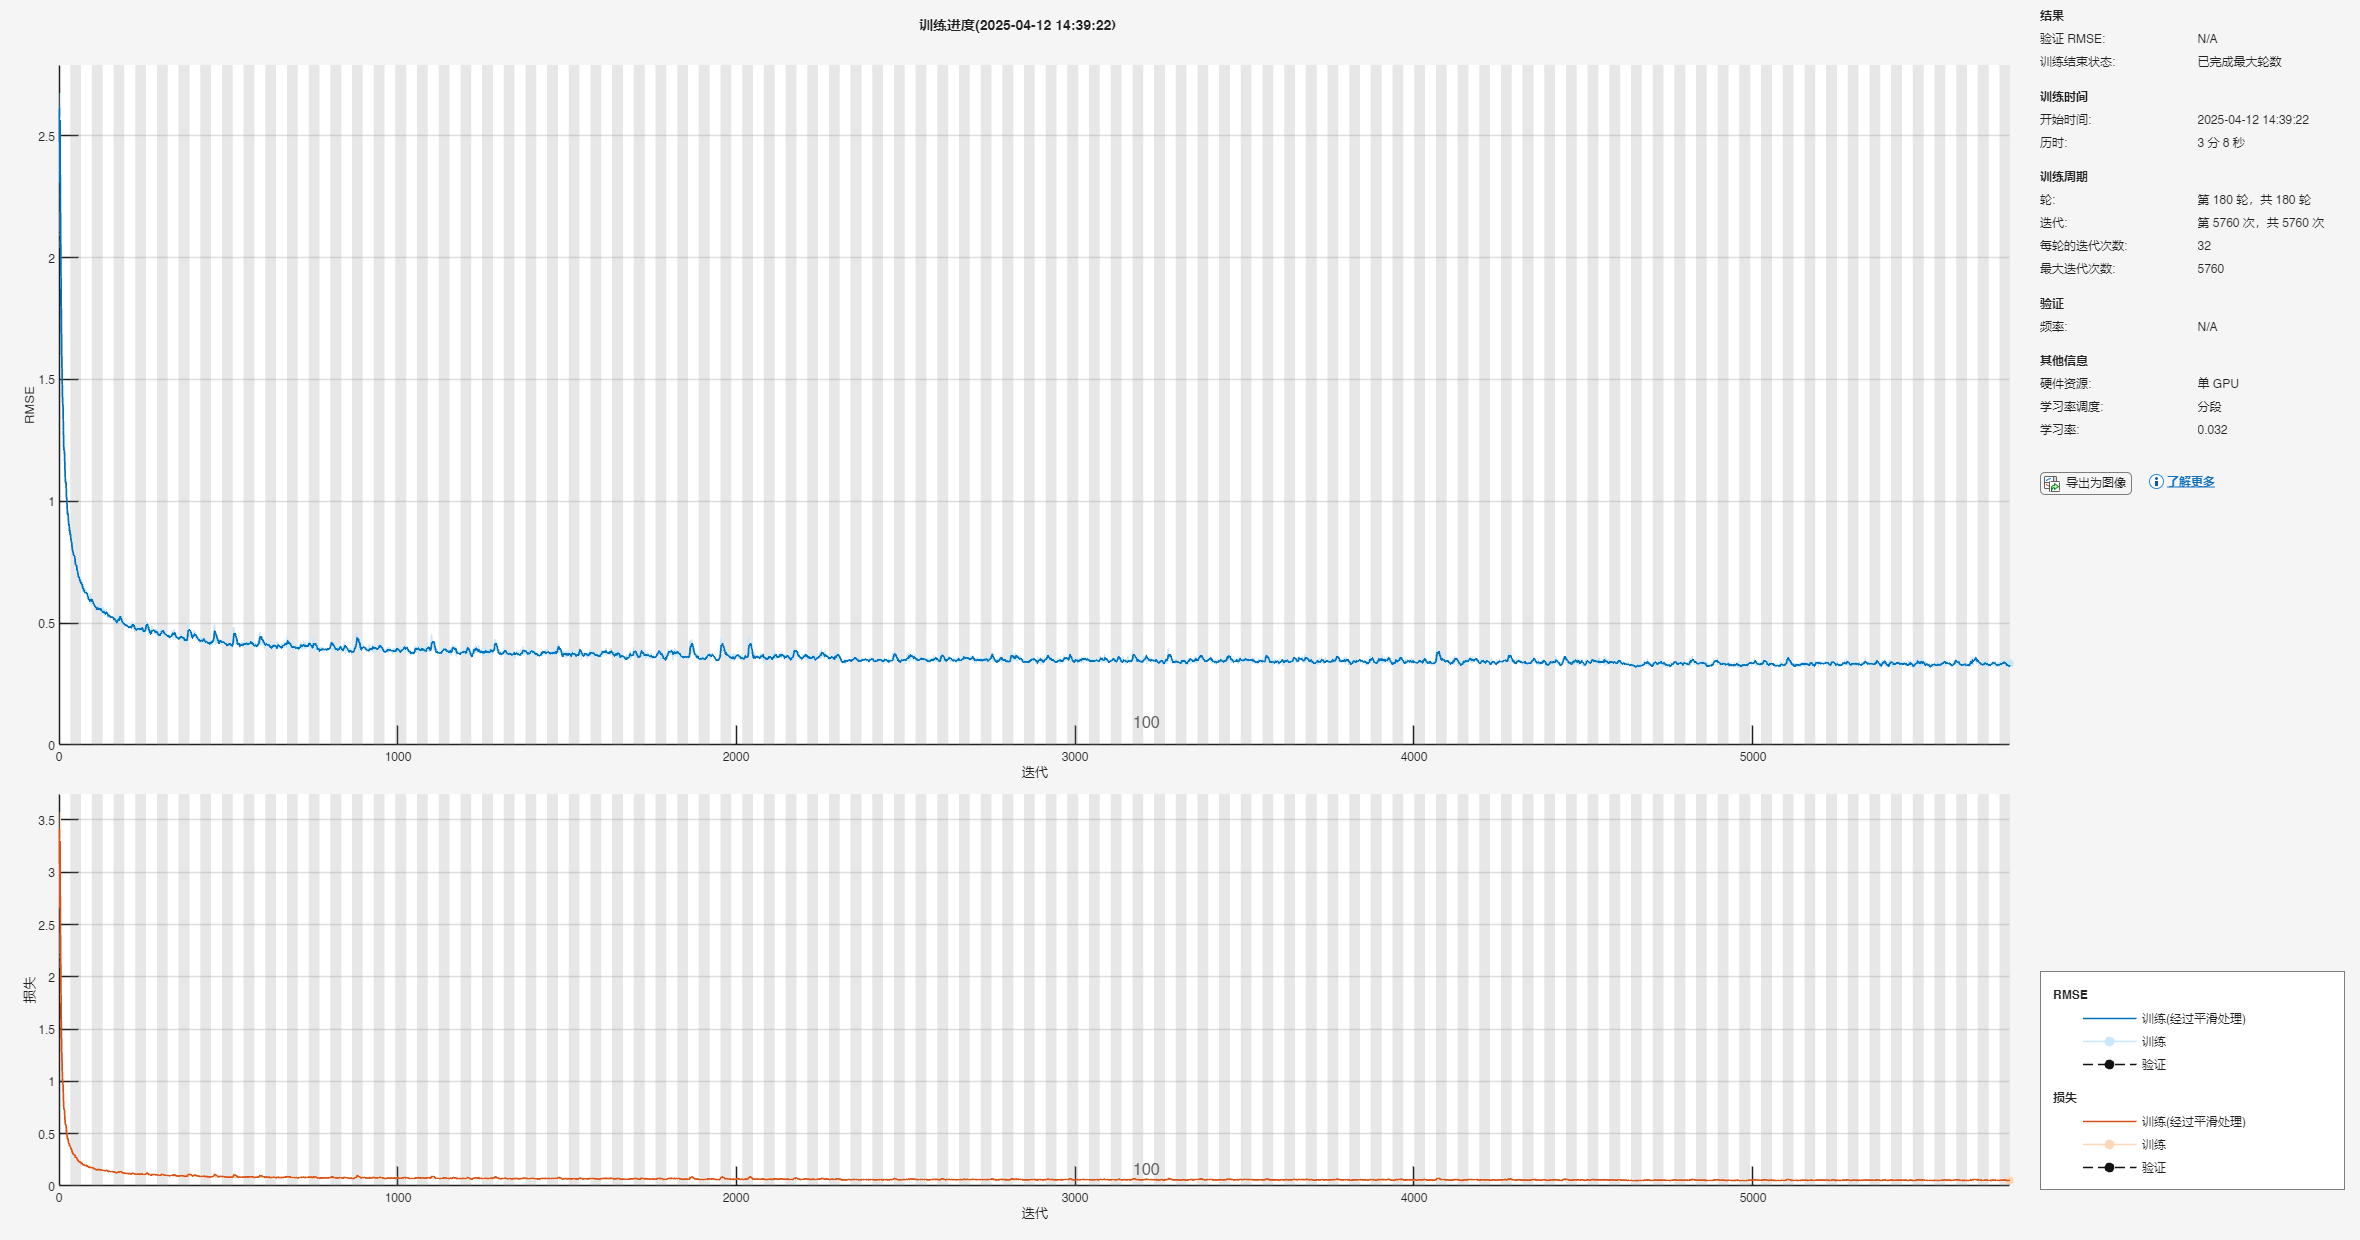

net = trainNetwork(input_train, output_train', layers, options);

### 保存神经网络

save('data\Semi_parameters\LSTM_net-20250412.mat', 'net');
analyzeNetwork(net);

### 第五步：验证神经网络

load('data/Semi_parameters/LSTM_net_backup.mat');

t_sim1 = predict(net, input_train);
t_sim2 = predict(net, input_test);
t_sim = double([t_sim1; t_sim2]);

Tsemi_idy_backup = T_idy + t_sim; 

% load('data\Semi_parameters\LSTM_net-20250412.mat');
% 
% t_sim1 = predict(net, input_train);
% t_sim2 = predict(net, input_test);
% t_sim = double([t_sim1; t_sim2]);
% 
% Tsemi_idy = T_idy + t_sim; 

## 番外：模型剪枝

% % 刚需MATLAB R2024a
% dlnet = dag2dlnetwork(net);    % 将SeriesNetwork转换为dlnetwork
% prunableNet = taylorPrunableNetwork(dlnet);

## 番外:模型投影

% % 参考网址：https://ww2.mathworks.cn/help/deeplearning/ref/compressnetworkusingprojection.html
% % 说明：按照matlab官方文档的建议，投影应在量化之前，剪枝之后
% 

## 番外：模型量化

% % 刚需MATLAB R2024a
% % quantizedNet 是由量化工具箱量化后的网络
% dlinput_train = dlarray(INPUT_TRAIN');
% dlinput_test = dlarray(INPUT_TEST');
% % t_sim1_quantized = predict(quantizedNet, input_train);
% t_sim1_quantized = predict(quantizedNet, INPUT_TRAIN);
% % t_sim2_quantized = predict(quantizedNet, input_test);
% t_sim2_quantized = predict(quantizedNet, dlinput_test);
% t_sim_quantized = [t_sim1_quantized; t_sim2_quantized];
% 
% Tsemi_idy_quantized = T_idy + t_sim_quantized; 
% Tsemi_idy = Tsemi_idy_quantized;

## 番外：加载RNN网络

load('data/Semi_parameters/RNN_net.mat');

t_sim1 = predict(net, INPUT_TRAIN');
t_sim2 = predict(net, INPUT_TEST');
t_sim = double([t_sim1; t_sim2]);

Tsemi_idy_RNN = T_idy + t_sim; 

### 画图

% traj_Ts = 0.001;
% 
% t = linspace(0, n_sample - 1, n_sample) * traj_Ts;
% 
% for i = 1 : 7
%     figure;
%     plot(t, T(:, i), 'b', 'LineWidth', 1.0); hold on;
%     plot(t, Tsemi_idy_backup(:, i), 'r', 'LineWidth', 1.0);
%     plot(t, T_idy(:, i), 'LineWidth', 1.0);
%     hold off;
%     ylabel('力矩(N/m)');
%     xlabel('时间(s)');
%     xlim([0, 120]);
%     legend('采集力矩', '半参数化模型', '标准模型');
%     % title(['No.', num2str(i), 'joint torque']);
%     legend('boxoff');
%     grid on;
% end

% tiledlayout(4, 2);
% 
% for i = 1 : 7
%     nexttile;
%     plot(t, T(:, i) - T_idy(:, i), 'b', 'LineWidth', 1.0); hold on;
%     plot(t, T(:, i) - Tsemi_idy, 'r', 'LineWidth', 1.0);
%     ylabel('力矩(Nm)');
%     legend('参数模型误差', '半参数模型误差')
%     title(['第', num2str(i), '关节辨识参数验证'])
% end

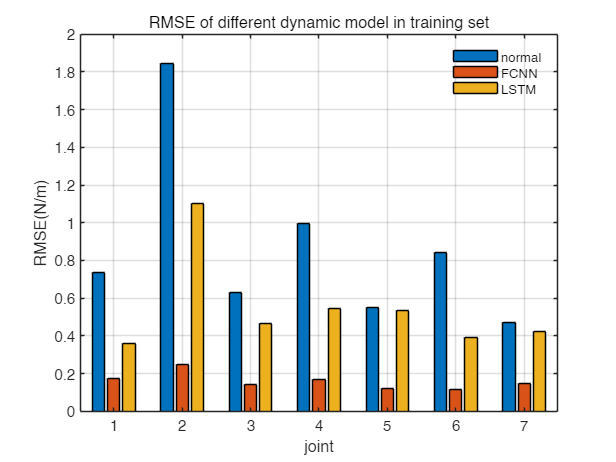

figure;
bar([rmse(T(1:split, :), T_idy(1:split, :), 1); ...
    rmse(T(1:split, :), Tsemi_idy_RNN(1:split, :), 1); ...
    rmse(T(1:split, :), Tsemi_idy_backup(1:split, :), 1); ...
    % rmse(T(1:split, :), Tsemi_idy(1:split, :), 1)...
    ]');

% legend('标准模型', 'FCNN模型', 'LSTM模型', '注意力机制模型');
legend('normal', 'FCNN', 'LSTM');
ylabel('RMSE(N/m)');
% xlabel('关节');
xlabel('joint');
title('RMSE of different dynamic model in training set');
legend('boxoff');
grid on;

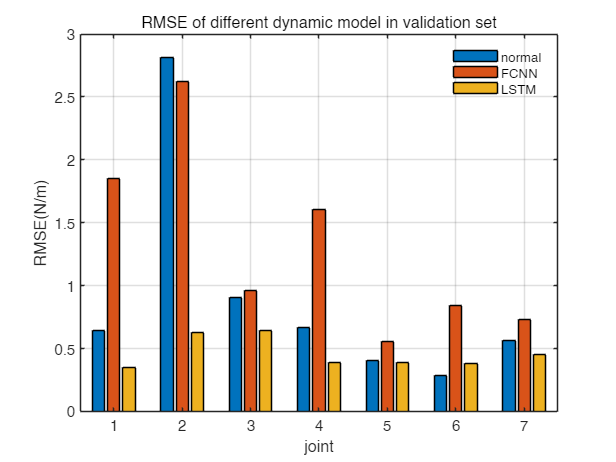

figure;
bar([rmse(T(split + 1 : end, :), T_idy(split + 1 : end, :), 1); ...
    rmse(T(split + 1 : end, :), Tsemi_idy_RNN(split + 1 : end, :), 1); ...
    rmse(T(split + 1 : end, :), Tsemi_idy_backup(split + 1 : end, :), 1); ...
    % rmse(T(split + 1 : end, :), Tsemi_idy(split + 1 : end, :), 1)...
    ]');
% legend('标准模型', 'FCNN模型', 'LSTM模型','注意力机制模型');
legend('normal', 'FCNN', 'LSTM');
ylabel('RMSE(N/m)');
% xlabel('关节');
xlabel('joint');
title(['RMSE of different dynamic model in validation set']);
legend('boxoff');
grid on;

[rmse(T(1:split, :), T_idy(1:split, :), 1); ...
    rmse(T(1:split, :), Tsemi_idy_RNN(1:split, :), 1); ...
    rmse(T(1:split, :), Tsemi_idy_backup(1:split, :), 1); ...
    rmse(T(1:split, :), Tsemi_idy(1:split, :), 1)...
    ]

ans =     0.7352    1.8423    0.6278    0.9959    0.5529    0.8398    0.4724
    0.1725    0.2472    0.1429    0.1666    0.1226    0.1145    0.1505
    0.3625    1.1025    0.4634    0.5432    0.5338    0.3903    0.4233
    0.5333    1.2026    0.4712    0.7649    0.4850    0.5686    0.4434


[rmse(T(split + 1 : end, :), T_idy(split + 1 : end, :), 1); ...
    rmse(T(split + 1 : end, :), Tsemi_idy_RNN(split + 1 : end, :), 1); ...
    rmse(T(split + 1 : end, :), Tsemi_idy_backup(split + 1 : end, :), 1); ...
    rmse(T(split + 1 : end, :), Tsemi_idy(split + 1 : end, :), 1)...
    ]

ans =     0.6421    2.8177    0.9088    0.6643    0.4045    0.2859    0.5663
    1.8513    2.6234    0.9635    1.6085    0.5540    0.8427    0.7276
    0.3459    0.6255    0.6432    0.3888    0.3856    0.3796    0.4560
    0.7699    2.8085    0.9121    1.4369    0.8078    1.2428    0.6206
